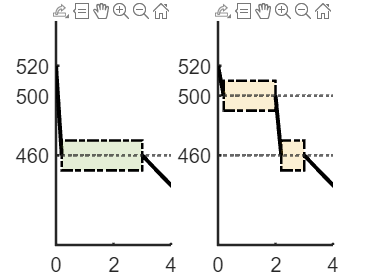

clear; close all; clc;



figure()



subplot(1,2,1)
hold on
% grid on
yline(460,'LineStyle',':','LineWidth',2)

plot([0 0.2], [520 460],'k', LineWidth=3)
time_range1 = [0.2 3];
patch([time_range1, fliplr(time_range1)], [[450 450] fliplr([470 470])], [0.4660 0.6740 0.1880], 'linestyle','-.','FaceAlpha', 0.2, LineWidth=2)

plot([3 6], [460 400],'k', LineWidth=3)



% title('1st Approach')
xlim([0 4])
ylim([400 550])
ax=gca;
ax.LineWidth=2;
ax.FontSize=15;
set(gca,'YTick',[460 500 520],'YTickLabel',{'460','500', '520'})





subplot(1,2,2)
hold on
% grid on

yline(500,'LineStyle',':','LineWidth',2)
yline(460,'LineStyle',':','LineWidth',2)
plot([0 0.2], [520 500],'k', LineWidth=3)

time_range2 = [0.2 2];
patch([time_range2, fliplr(time_range2)], [[490 490] fliplr([510 510])], [0.9290 0.6940 0.1250], 'linestyle','-.','FaceAlpha', 0.2, LineWidth=2)
plot([2 2.2], [500 460],'k', LineWidth=3)

time_range2 = [2.2 3];
patch([time_range2, fliplr(time_range2)], [[450 450] fliplr([470 470])], [0.9290 0.6940 0.1250], 'linestyle','-.','FaceAlpha', 0.2, LineWidth=2)

plot([3 6], [460 400],'k', LineWidth=3)

% title('2nd Approach')
xlim([0 4])
ylim([400 550])
ax=gca;
ax.LineWidth=2;
ax.FontSize=15;
set(gca,'YTick',[460 500 520],'YTickLabel',{'460','500', '520'})

Orbit injection error

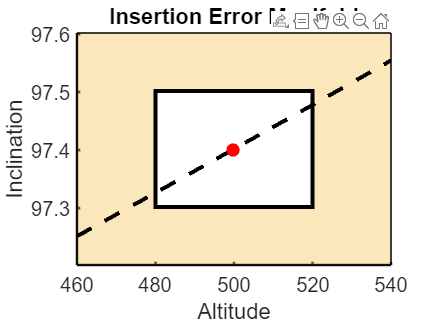



clear; close all; clc

altitude = 500;
i = rad2deg(acos(-0.098922 * (1 + (altitude ./ 6378.137)).^(7/2)));
h_err = 20;
i_err = 0.1;

h_SSO = 460:1:560;
i_SSO = rad2deg(acos(-0.098922 * (1 + (h_SSO ./ 6378.137)).^(7/2)));


left_lcorner = [altitude-h_err, i-i_err];
right_lcorner = [altitude+h_err, i-i_err];
left_ucorner = [altitude-h_err, i+i_err];
right_ucorner = [altitude+h_err, i+i_err];

figure()
hold on

buffer = 2;
% Define the outer rectangle corners, covering the plot area
outer_x = [altitude-buffer*h_err, altitude+buffer*h_err, altitude+buffer*h_err, altitude-buffer*h_err];
outer_y = [i-buffer*i_err, i-buffer*i_err, i+buffer*i_err, i+buffer*i_err];

% Plot the filled background, leaving the square as a hole
fill(outer_x, outer_y, [0.9290 0.6940 0.1250], 'FaceAlpha', 0.3); % Background color and transparency

% Overlay the square as an unfilled patch to create a "hole" effect
x_coords = [left_lcorner(1), right_lcorner(1), right_ucorner(1), left_ucorner(1)];
y_coords = [left_lcorner(2), right_lcorner(2), right_ucorner(2), left_ucorner(2)];
patch(x_coords, y_coords, 'w', 'EdgeColor', 'k', 'FaceColor', 'white', LineWidth=3); % Square with white fill

plot(h_SSO, i_SSO,'LineStyle','--','LineWidth',3,'Color','k')
plot(altitude, i, 'r.', 'LineWidth', 2, 'MarkerSize', 30);


% Set axis limits to center the square in the plot
xlim([altitude - buffer*h_err, altitude + buffer*h_err]);
ylim([i - buffer*i_err, i + buffer*i_err]);

% Set axis labels and other options as needed
xlabel('Altitude');
ylabel('Inclination');
title('Insertion Error Manifold');
ax=gca;
ax.LineWidth=2;
ax.FontSize=15;
hold off;